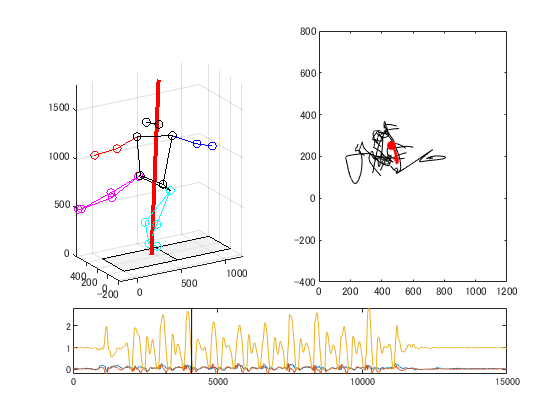

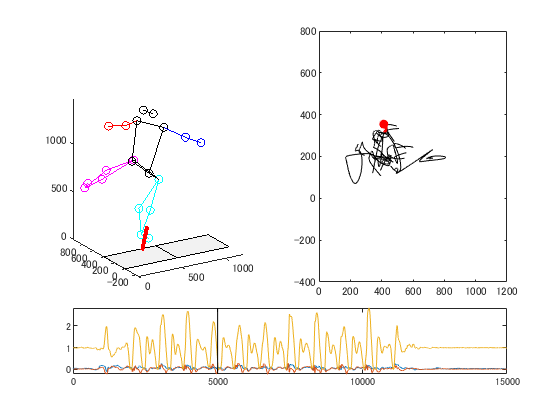

clear
close all
clc


% *** 実験実習で測定計測したデータ を load***
fileName = 'Data_Ballet' ; % ←　バレエ
load(fileName) ;

% grf, Markers, cop が構造体としてまとめられているので、別々の変数として定義する
grfs = Data.Forces ;
grf = grfs(:,1:3) + grfs(:,4:6) ;
Markers = Data.Markers ;
cop = Data.CoP ;



figure ;
grfFigScale = 700 ;

h1 = subplot(4,2,[1,3,5]) ;
h2 = subplot(4,2,[2,4,6]) ;
h3 = subplot(4,2,[7,8]) ;

% grf
axes(h3) ;
plot(grf) ;
H.line1 = lineplot(0, 'v', 'k') ;

% cop
axes(h2) ;
plot(cop(:,1), cop(:,2), 'k-', 'linewidth', 0.3) ; hold on
set(gca, 'xlim', [0,1200], 'ylim', [-400,800])

H.copTra = plot(cop(1:100,1), cop(1:100,2), 'r', 'linewidth', 2) ;
H.copPoint = plot(cop(1,1), cop(1,2), 'ro', 'markerfacecolor', 'r') ;
hold off

% force plate
for iFrame = 4000:100:5000
    axes(h1) ; grid on
    set(H.line1, 'xdata', [1,1]*iFrame)
    
    % grf
    fx = grf(iFrame,1) ;
    fy = grf(iFrame,2) ;
    fz = grf(iFrame,3) ;
    copX = cop(iFrame,1) ;
    copY = cop(iFrame,2) ;
    set(h1, 'NextPlot', 'replace') ;
    plot3([0,fx]*grfFigScale+copX, [0,fy]*grfFigScale+copY, [0,fz]*grfFigScale, 'r-', 'linewidth', 3)
    set(h1, 'NextPlot', 'add') ;
    
    set(H.copPoint, 'xdata', copX, 'YData', copY) ;
    dur = 500 ;
    set(H.copTra, 'xdata', cop([max(iFrame-dur,1):iFrame],1), 'YData', cop([max(iFrame-dur,1):iFrame],2)) ;
    
    
    % stick picture
    
    % head
    MarkerNames = {'REar', 'LEar'} ;
    stickPicture(Markers, MarkerNames, iFrame, 'xyz', 'ko-') ;
    % shoulder-arm
    MarkerNames = {'RWrist', 'RElbow', 'RShoulder'} ;
    stickPicture(Markers, MarkerNames, iFrame, 'xyz', 'ro-') ;
    MarkerNames = {'LShoulder', 'LElbow', 'LWrist'} ;
    stickPicture(Markers, MarkerNames, iFrame, 'xyz', 'bo-') ;
    % trunk-pelvis
    MarkerNames = {'RShoulder', 'LShoulder', 'LASIS', 'RASIS', 'RShoulder'} ;
    stickPicture(Markers, MarkerNames, iFrame, 'xyz', 'ko-') ;
    MarkerNames = {'RASIS', 'LASIS', 'LHip', 'RHip', 'RASIS'} ;
    stickPicture(Markers, MarkerNames, iFrame, 'xyz', 'ko-') ;
    % right leg
    MarkerNames = {'RToe', 'RAnkle', 'RKneeMed', 'RHip', 'RKneeLat', 'RAnkle'} ;
    stickPicture(Markers, MarkerNames, iFrame, 'xyz', 'mo-') ;
    % left leg
    MarkerNames = {'LToe', 'LAnkle', 'LKneeMed', 'LHip', 'LKneeLat', 'LAnkle'} ;
    stickPicture(Markers, MarkerNames, iFrame, 'xyz', 'co-') ;
    
    % fp
    xx = [0, 600, 600, 0, 0] ;
    yy = [0, 0, 400, 400, 0] ;
    zz = [0,0,0,0,0] ;
    cc = [1,1,1]*0.9 ;
    
    patch(xx, yy, zz, cc, 'facealpha', 0.5) ;
    xx = [0, 600, 600, 0, 0]+600.5 ;
    patch(xx, yy, zz, cc, 'facealpha', 0.5) ;
    
    CameraPosition = [-5000, -9000, 5000] ;
    CameraTarget = [600, 200, 1000] ;
    set(gca, 'CameraPosition', CameraPosition, 'CameraTarget', CameraTarget)
    axis equal
    
end